# Tutorial 3

## Worksheet 4.1

clear
format long
S = 0;
n = 0;
for n = 0:10
    S = S + 1 / factorial(n)
    n = n + 1;
end

S =      1


S =      2


S =    2.500000000000000


S =    2.666666666666667


S =    2.708333333333333


S =    2.716666666666666


S =    2.718055555555555


S =    2.718253968253968


S =    2.718278769841270


S =    2.718281525573192


S =    2.718281801146385


exp(1)

ans =    2.718281828459045


## Exercise 4.2.1

for i = 2:2:20
    disp(i)
end

     2

     4

     6

     8

    10

    12

    14

    16

    18

    20



## Exercise 4.2.2

for i = 1:10
    disp(i^2)
end

     1

     4

     9

    16

    25

    36

    49

    64

    81

   100



## Exercise 4.2.3

sum_of_integers(40), 40 * (40 + 1) / 2

ans =    820


ans =    820


## Exercise 4.3.1

array_sum([3, 4, 5])

ans =     12


## Exercise 4.4.1

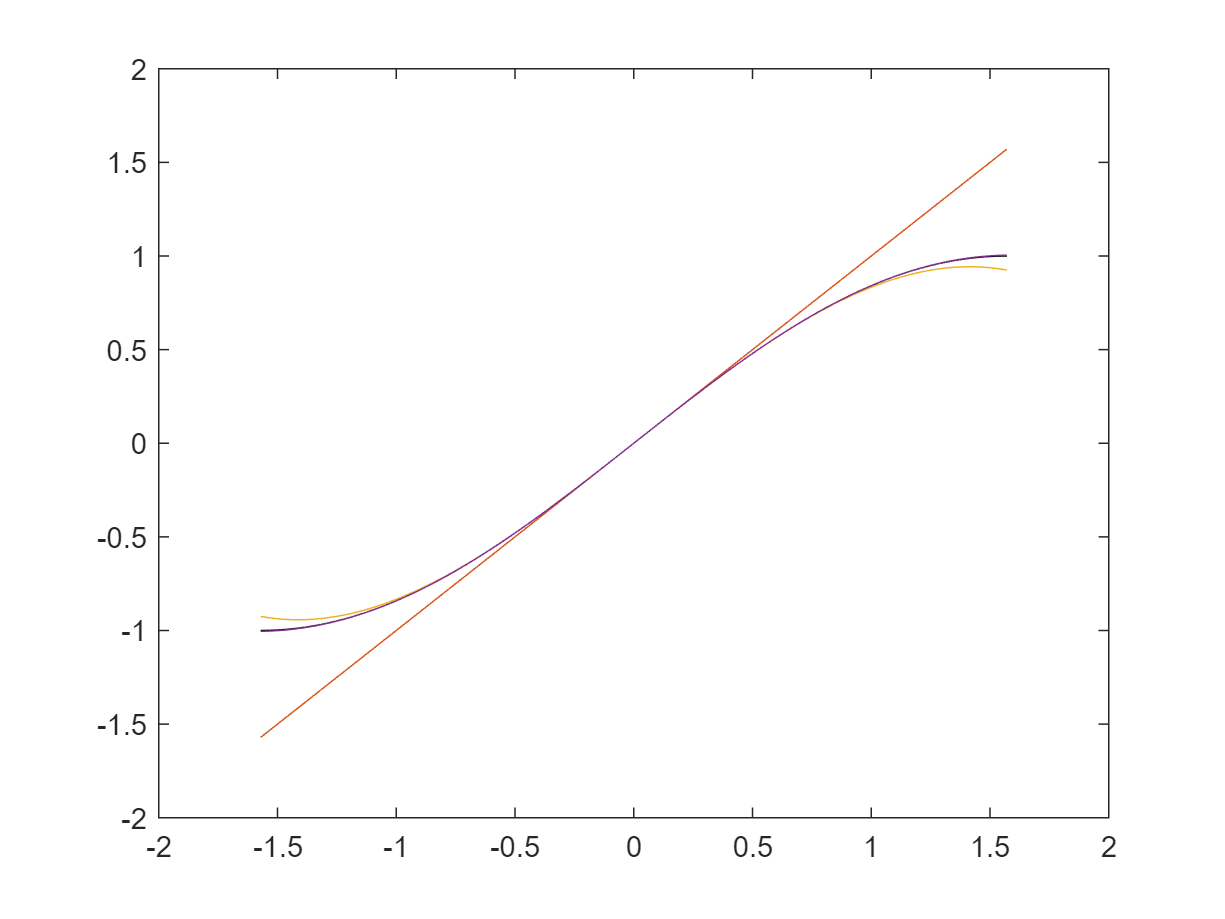

clear
f = @(x) sin(x);

x = linspace(-pi / 2, pi / 2, 100);
x0 = 0;

dn = 2;
N = 5;
n = 1:dn:N;

if min(n) == 0
    offset = min(n) + 1;
else
    offset = 0;
end

P = zeros([length(n), N + 1]);
for i = n
    P(offset + i, :) = [zeros([1, N - i]), taylor(f, x0, i)];
end

figure
plot(x, f(x), 'k')
hold on
for i = n
    plot(x, polyval(P(offset + i, :), x - x0))
end

## Exercise 4.4.2

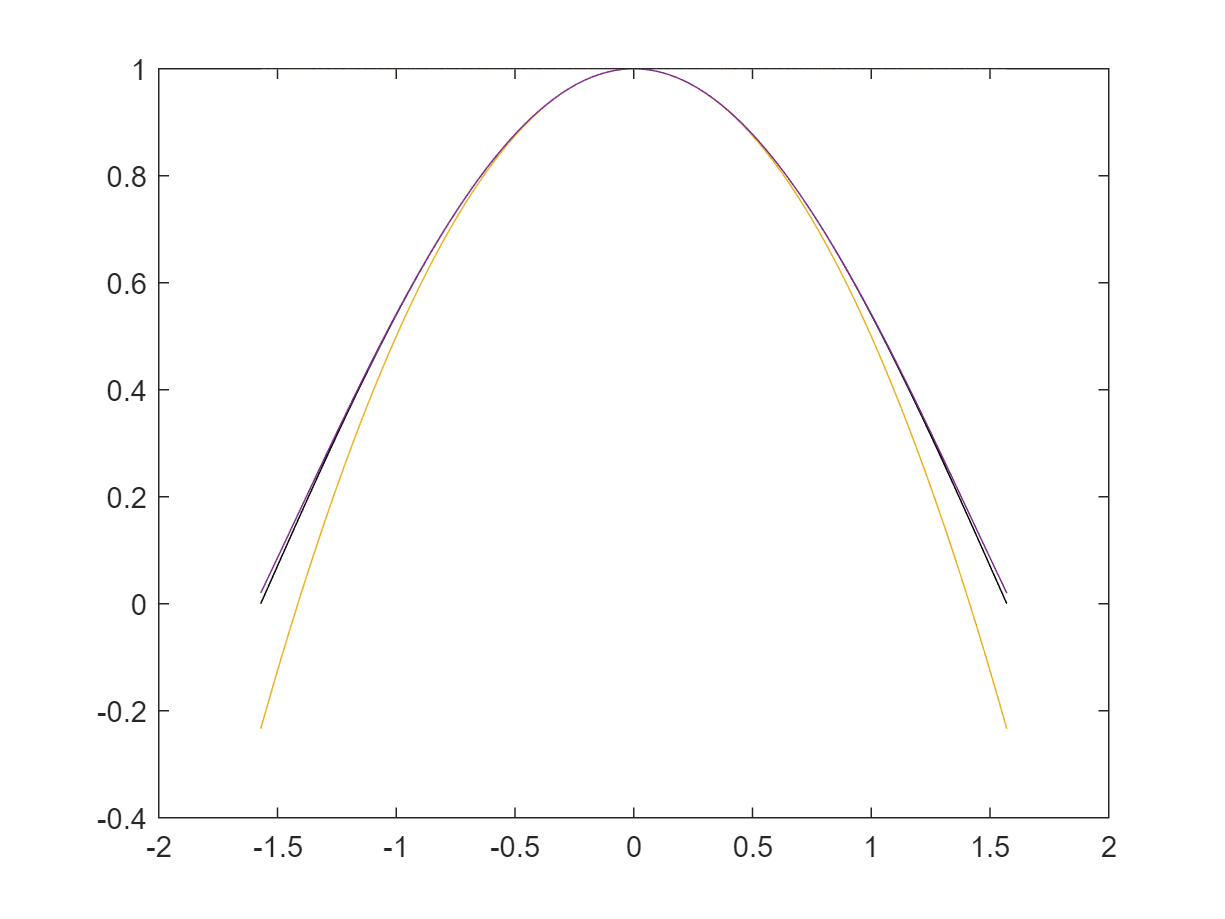

clear
f = @(x) cos(x);

x = linspace(-pi / 2, pi / 2, 100);
x0 = 0;

dn = 2;
N = 4;
n = 0:dn:N;

if min(n) == 0
    offset = min(n) + 1;
else
    offset = 0;
end

P = zeros([length(n), N + 1]);
for i = n
    P(offset + i, :) = [zeros([1, N - i]), taylor(f, x0, i)];
end

figure
plot(x, f(x), 'k')
hold on
for i = n
    plot(x, polyval(P(offset + i, :), x - x0))
end

function S = sum_of_integers(n)
    S = 0;
    for i = 1:n
        S = S + i;
    end
end

function S = array_sum(v)
    S = sum(v);
end